clear;
cd '/Users/davidchung/Documents/ACM/Spring 2019/Statistical Models and Regression/Textbook Datasets/Appendices'
data = importdata('data-table-B-15_csv.csv', ',');
y = data.data(:, 1);
X = data.data(:, [2:6]);
n = size(X,1)

n = 60

X = [ones(n,1) X];
cd ..; cd ..;
K = size(X, 2) - 1

K = 5

Construct regression model with all regressors:

beta_hat_full = inv(X'*X)*X'*y

beta_hat_full =   995.6365
    1.4073
  -14.8014
    3.1991
   -0.1080
    0.3552


SS_tot = y'*y - (sum(y))^2/n

SS_tot = 2.2828e+05

SS_R_full = beta_hat_full'*X'*y - (sum(y))^2/n

SS_R_full = 1.5399e+05

R2_full = SS_R_full/SS_tot

R2_full = 0.6746

SS_res_full = SS_tot - SS_R_full

SS_res_full = 7.4289e+04

MS_res_full = SS_res_full/(n-K-1)

MS_res_full = 1.3757e+03


y_hat = X*beta_hat_full;
e = y-y_hat;
H = X*inv(X'*X)*X';

Construct model with all possible regressions method:

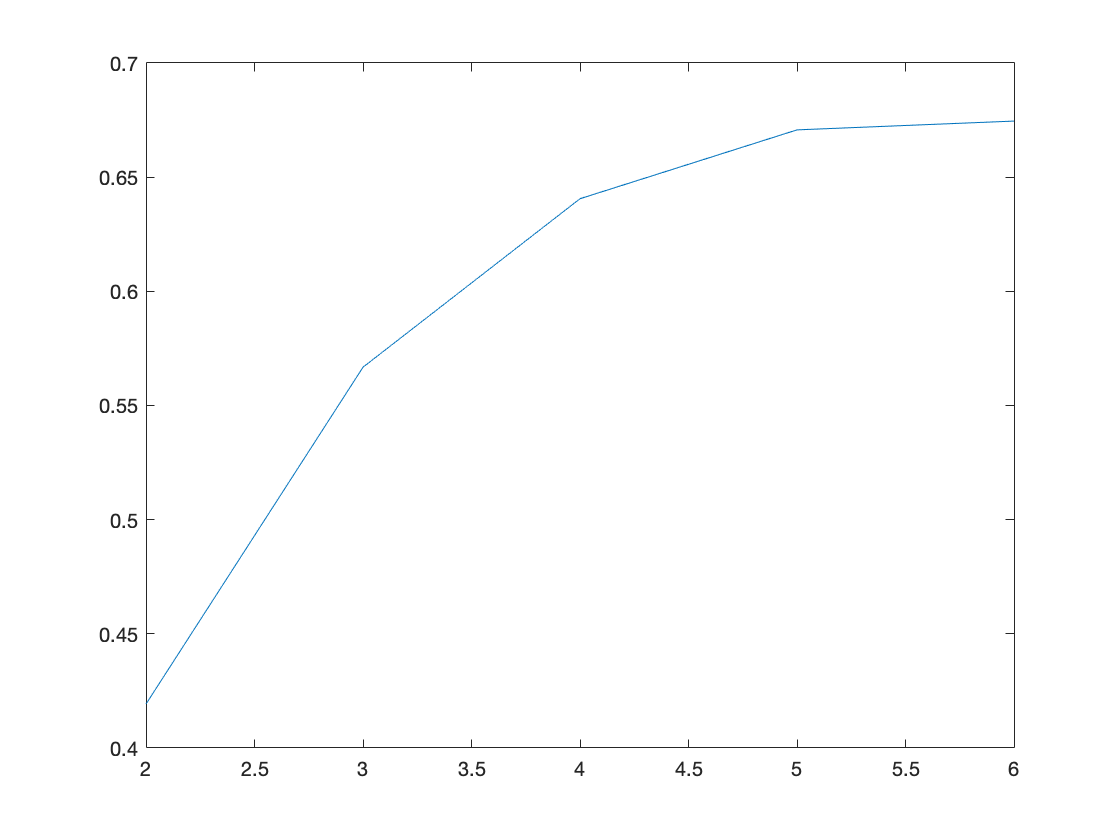

% 1 regressor (p=2)
p = 2;
R2_2 = [];
MS_res_2 = [];
Cp_2 = [];
for i=1:K
    X_test = [ones(n,1) X(:,i+1)];
    beta_hat = inv(X_test'*X_test)*X_test'*y;
    SS_R = beta_hat'*X_test'*y - (sum(y))^2/n;
    SS_res = SS_tot - SS_R;
    R2_2 = [R2_2 SS_R/SS_tot];
    MS_res_2 = [MS_res_2 SS_res/(n-p)];
    Cp_2 = [Cp_2 SS_res/MS_res_full - n + 2*p];
    
    if SS_R/SS_tot >= max(R2_2)
        R2_2_max = i;
    end
    if SS_res/(n-2) <= min(MS_res_2)
        MS_res_2_min = i;
    end
    if SS_res/MS_res_full - n + 2*p <= min(Cp_2)
        Cp_2_min = i;
    end
end % x3

% 2 regressors (p=3)
p = 3;
R2_3 = [];
MS_res_3 = [];
Cp_3 = [];
for i=1:K
    for j=i+1:K
        X_test = [ones(n,1) X(:,i+1) X(:,j+1)];
        beta_hat = inv(X_test'*X_test)*X_test'*y;
        SS_R = beta_hat'*X_test'*y - (sum(y))^2/n;
        SS_res = SS_tot - SS_R;
        R2_3 = [R2_3 SS_R/SS_tot];
        MS_res_3 = [MS_res_3 SS_res/(n-p)];
        Cp_3 = [Cp_3 SS_res/MS_res_full - n + 2*p];
    
        if SS_R/SS_tot >= max(R2_3)
            R2_3_max = [i j];
        end
        if SS_res/(n-p) <= min(MS_res_3)
            MS_res_3_min = [i j];
        end
        if SS_res/MS_res_full - n + 2*p <= min(Cp_3)
            Cp_3_min = [i j];
        end
    end  
end % x2, x3

% 3 regressors (p=4)
p = 4;
R2_4 = [];
MS_res_4 = [];
Cp_4 = [];
for i=1:K
    for j=i+1:K
        for l=j+1:K
            X_test = [ones(n,1) X(:,i+1) X(:,j+1) X(:,l+1)];
            beta_hat = inv(X_test'*X_test)*X_test'*y;
            SS_R = beta_hat'*X_test'*y - (sum(y))^2/n;
            SS_res = SS_tot - SS_R;
            R2_4 = [R2_4 SS_R/SS_tot];
            MS_res_4 = [MS_res_4 SS_res/(n-p)];
            Cp_4 = [Cp_4 SS_res/MS_res_full - n + 2*p];
    
            if SS_R/SS_tot >= max(R2_4) && SS_R/SS_tot <=1
                R2_4_max = [i j l];
            end
            if SS_res/(n-p) <= min(MS_res_4)
                MS_res_4_min = [i j l];
            end
            if SS_res/MS_res_full - n + 2*p <= min(Cp_4)
                Cp_4_min = [i j l];
            end
        end  
    end  
end % x1, x3, x5

% 4 regressors (p=5)
p = 5;
R2_5 = [];
MS_res_5 = [];
Cp_5 = [];
for i=1:K
    for j=i+1:K
        for l=j+1:K
            for m=l+1:K
                X_test = [ones(n,1) X(:,i+1) X(:,j+1) X(:,l+1) X(:,m+1)];
                beta_hat = inv(X_test'*X_test)*X_test'*y;
                SS_R = beta_hat'*X_test'*y - (sum(y))^2/n;
                SS_res = SS_tot - SS_R;
                R2_5 = [R2_5 SS_R/SS_tot];
                MS_res_5 = [MS_res_5 SS_res/(n-p)];
                Cp_5 = [Cp_5 SS_res/MS_res_full - n + 2*p];
    
                if SS_R/SS_tot >= max(R2_5) && SS_R/SS_tot <=1
                    R2_5_max = [i j l m];
                end
                if SS_res/(n-p) <= min(MS_res_5)
                    MS_res_5_min = [i j l m];
                end
                if SS_res/MS_res_full - n + 2*p <= min(Cp_5)
                    Cp_5_min = [i j l m];
                end
            end 
        end   
    end   
end % x1, x2, x3, x5

% Plot R2(p), MS_res(p), Cp
figure(1) % R2_p
plot([2 3 4 5 6], [max(R2_2), max(R2_3), max(R2_4), max(R2_5), R2_full]);

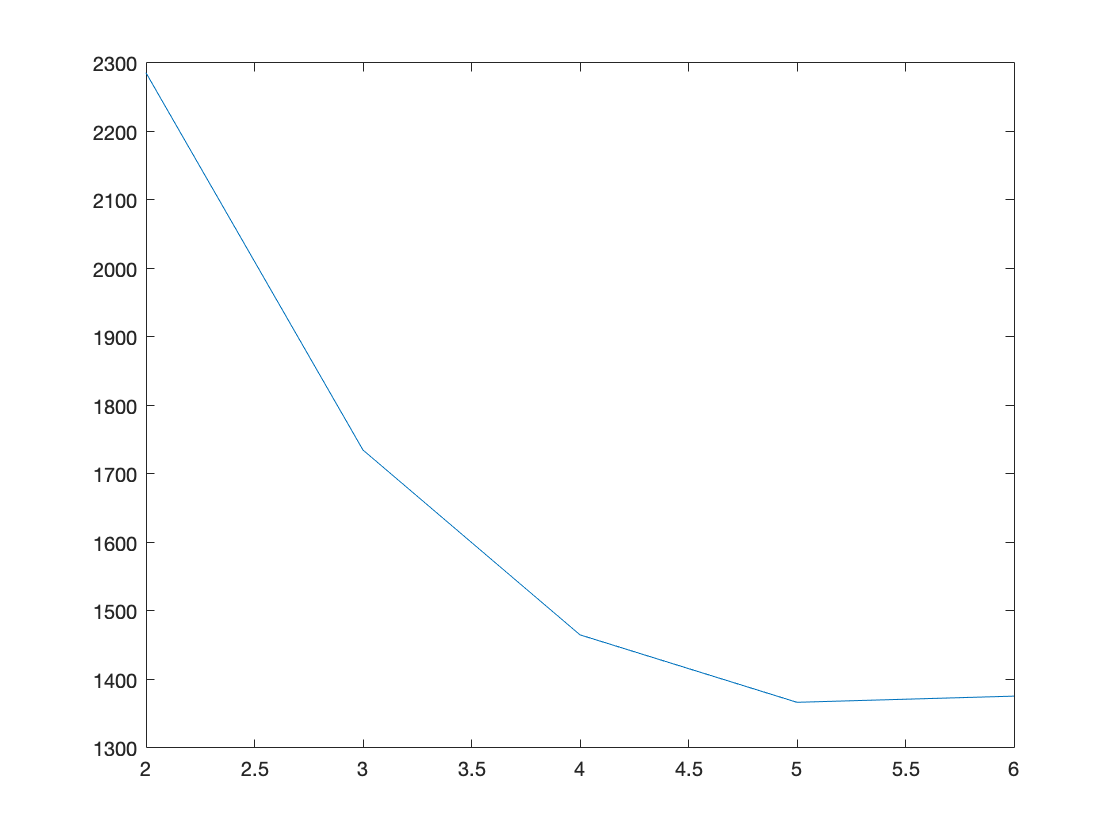

figure(2) % MS_res(p)
plot([2 3 4 5 6], [min(MS_res_2) min(MS_res_3) min(MS_res_4) min(MS_res_5) MS_res_full]);

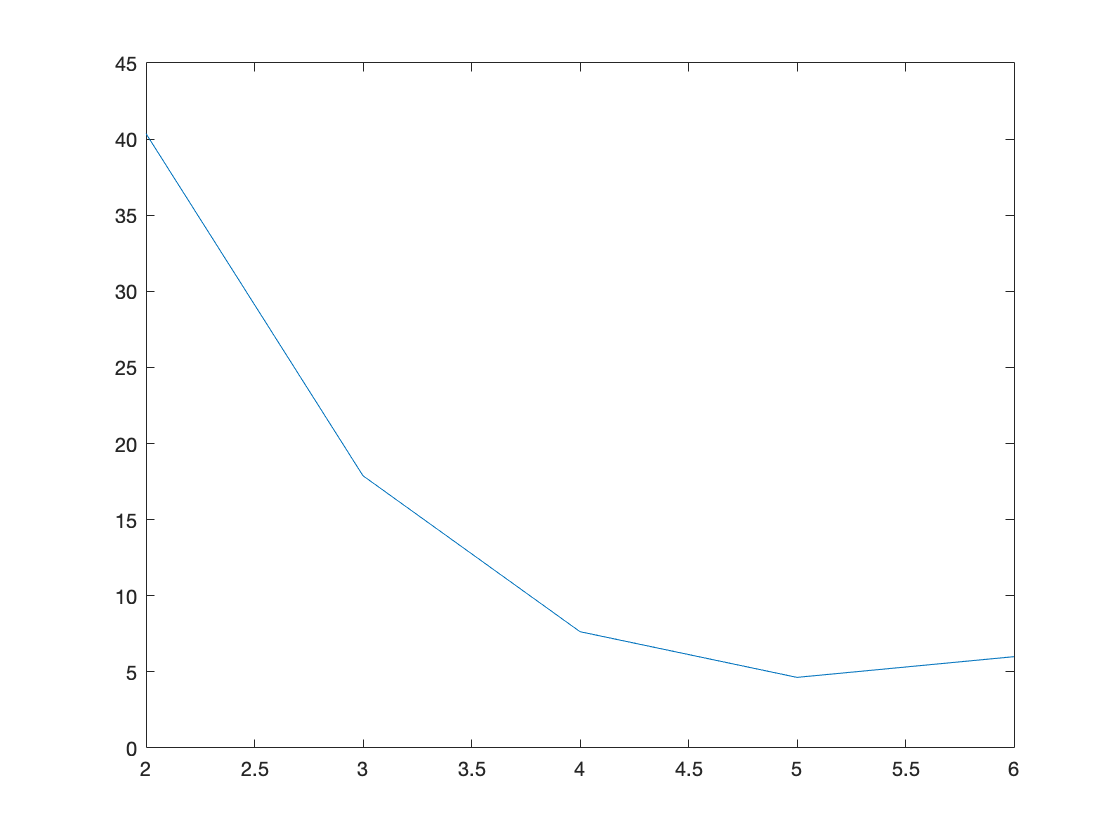

figure(3) %C_p
plot([2 3 4 5 6], [min(Cp_2) min(Cp_3) min(Cp_4) min(Cp_5) 6]);

Select model with x1, x2, x3, x5. Assess normality assumption and model adequacy:

p=5;
X_ap = X(:,[1:4 6]);
beta_hat_ap = inv(X_ap'*X_ap)*X_ap'*y

beta_hat_ap =   995.8224
    1.6350
  -15.5697
    3.0998
    0.3263


SS_R_ap = beta_hat_ap'*X_ap'*y - (sum(y))^2/n

SS_R_ap = 1.5311e+05

SS_res_ap = SS_tot - SS_R_ap

SS_res_ap = 7.5169e+04

MS_res_ap = SS_res_ap/(n-p)

MS_res_ap = 1.3667e+03

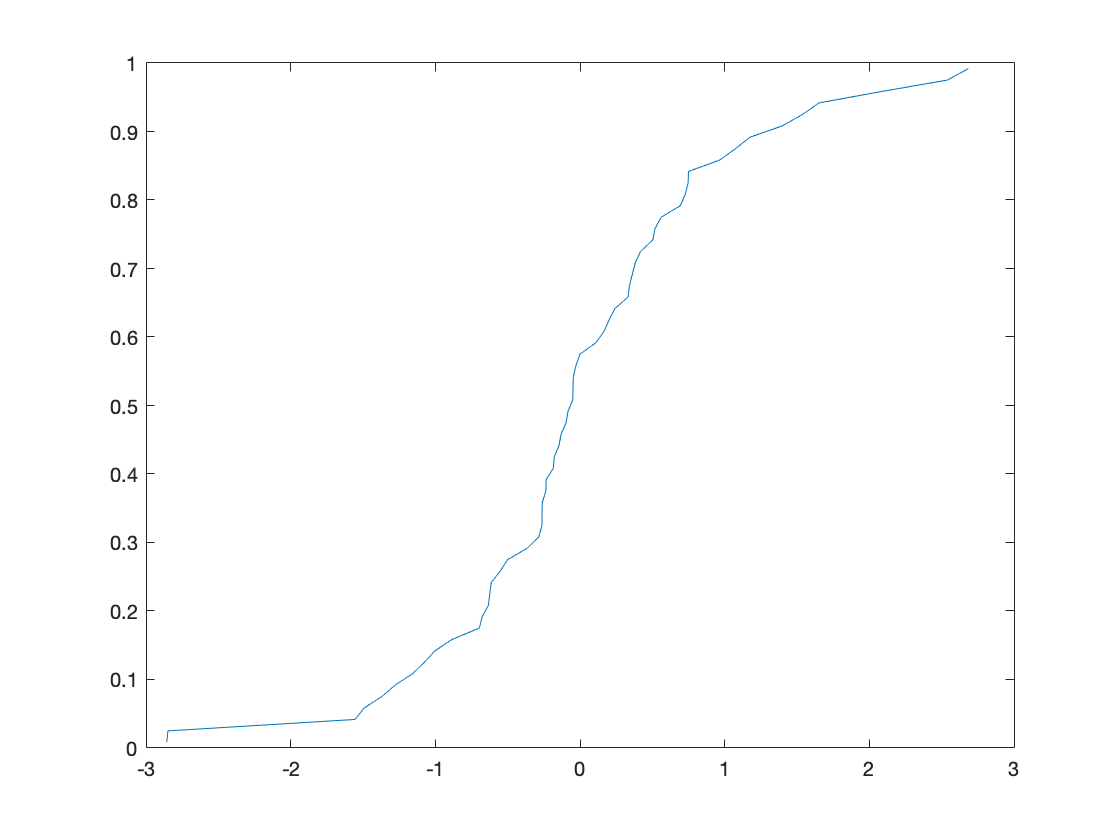


y_hat_ap = X_ap*beta_hat_ap;
e_ap = y - y_hat_ap;
H_ap = X_ap*inv(X_ap'*X_ap)*X_ap';

% Normality assumption

for i=1:n
    S_2i = ((n-p)*MS_res_ap - (e_ap(i))^2/(1-H_ap(i,i)))/(n-p-1);
    t_ap(i) = e_ap(i)/sqrt(S_2i*(1-H_ap(i,i)));
    r_ap(i) = e_ap(i)/sqrt(MS_res_ap*(1-H_ap(i,i)));
    P_ap(i) = (i-0.5)/n;
end
figure(1)
t_sorted = sort(t_ap)';
plot(t_sorted, P_ap);

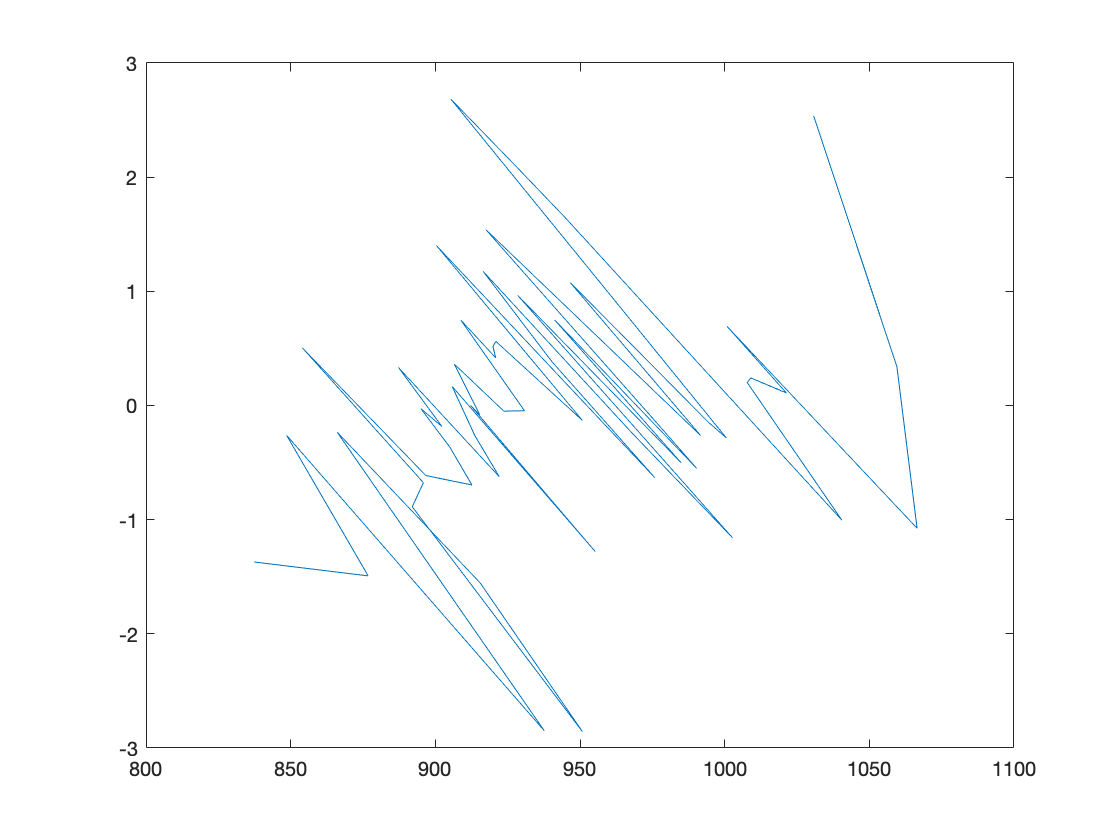


% Residual plots
figure(2)
plot(y_hat_ap, t_ap);

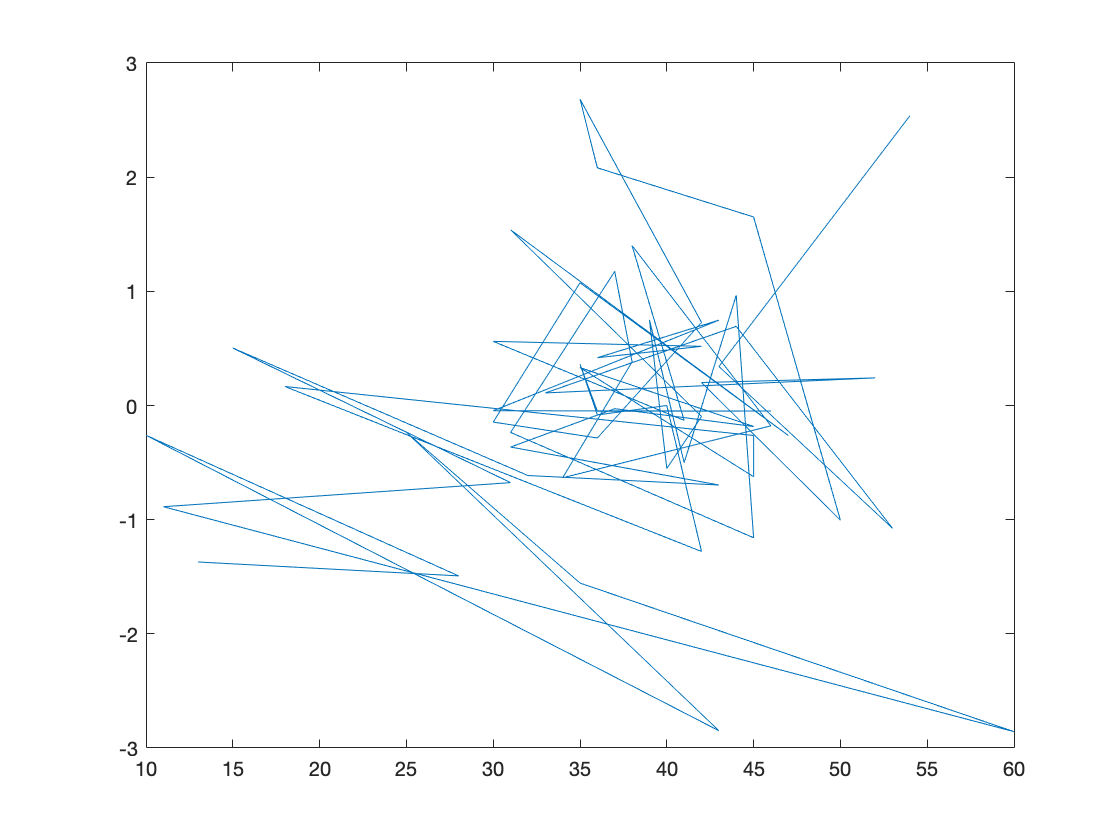

figure(3) 
plot(X_ap(:,2), t_ap); % x1

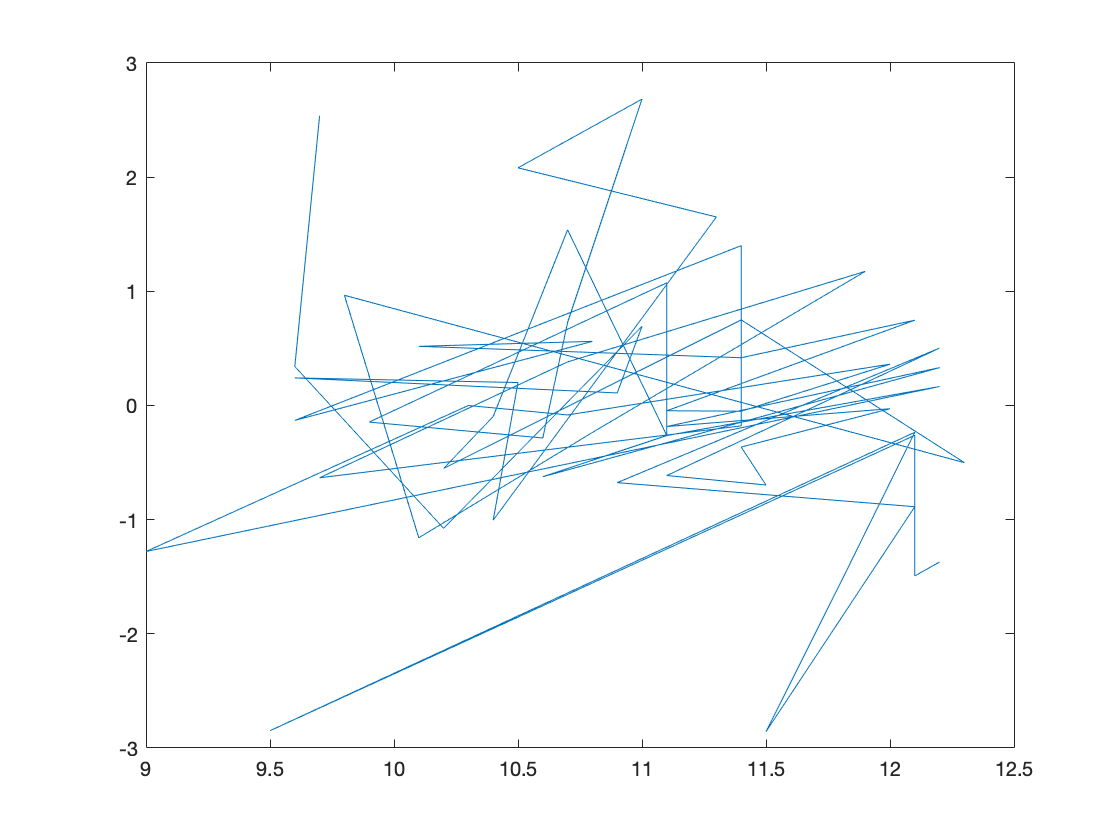

figure(4) 
plot(X_ap(:,3), t_ap); % x2

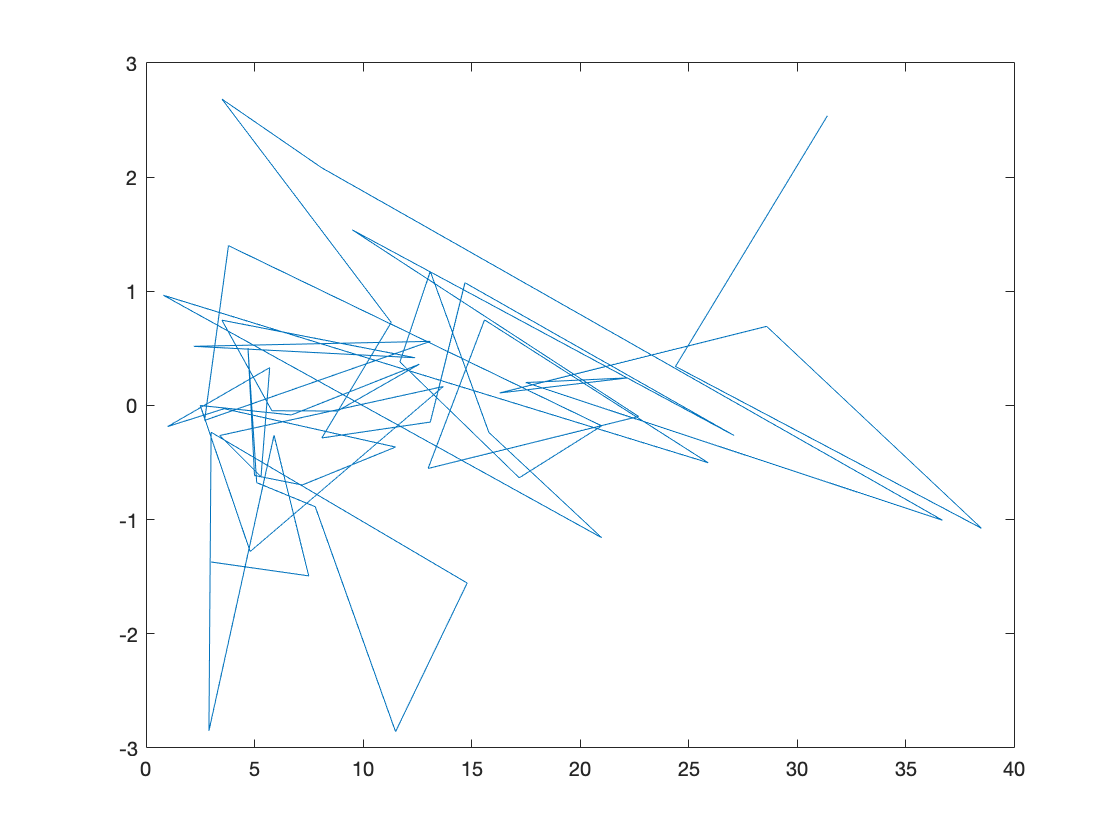

figure(5)
plot(X_ap(:,4), t_ap); % x3

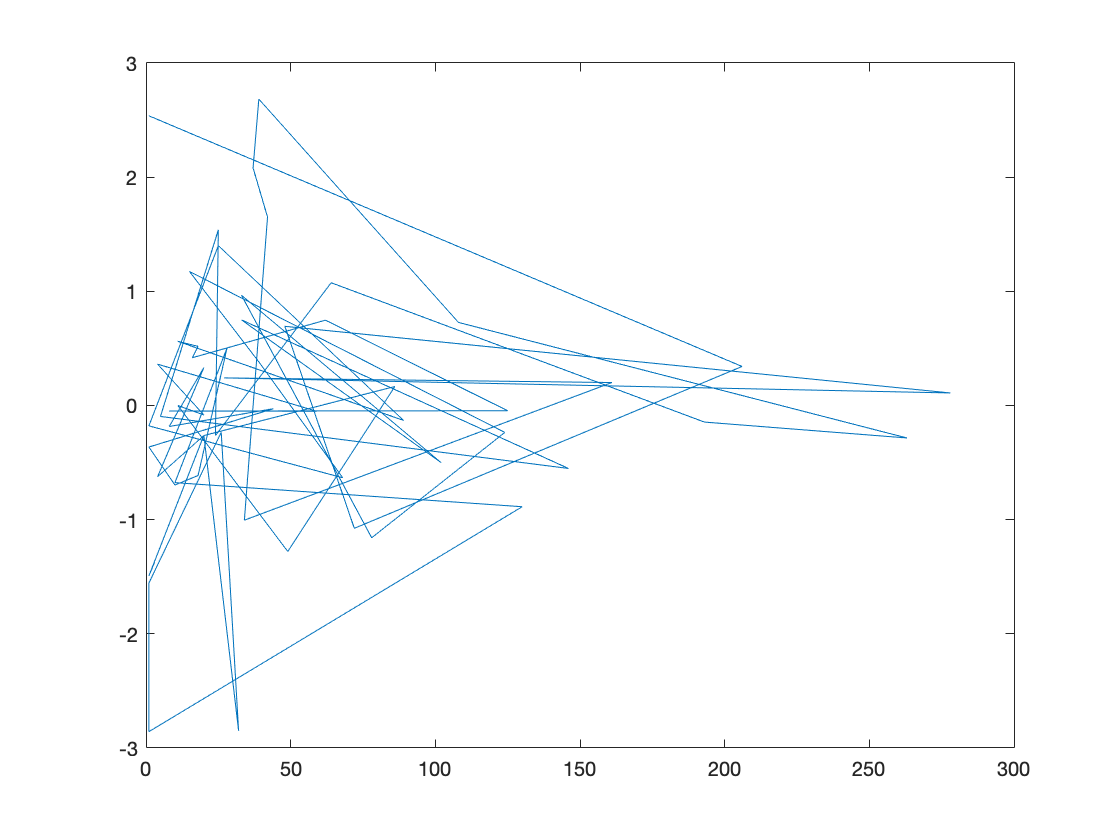

figure(6)
plot(X_ap(:,5), t_ap) % x5

Response appears to have nonlinear relationship with x3, x5 - plot scatterplots of x3, x5 vs y -  apply natural log transformation:

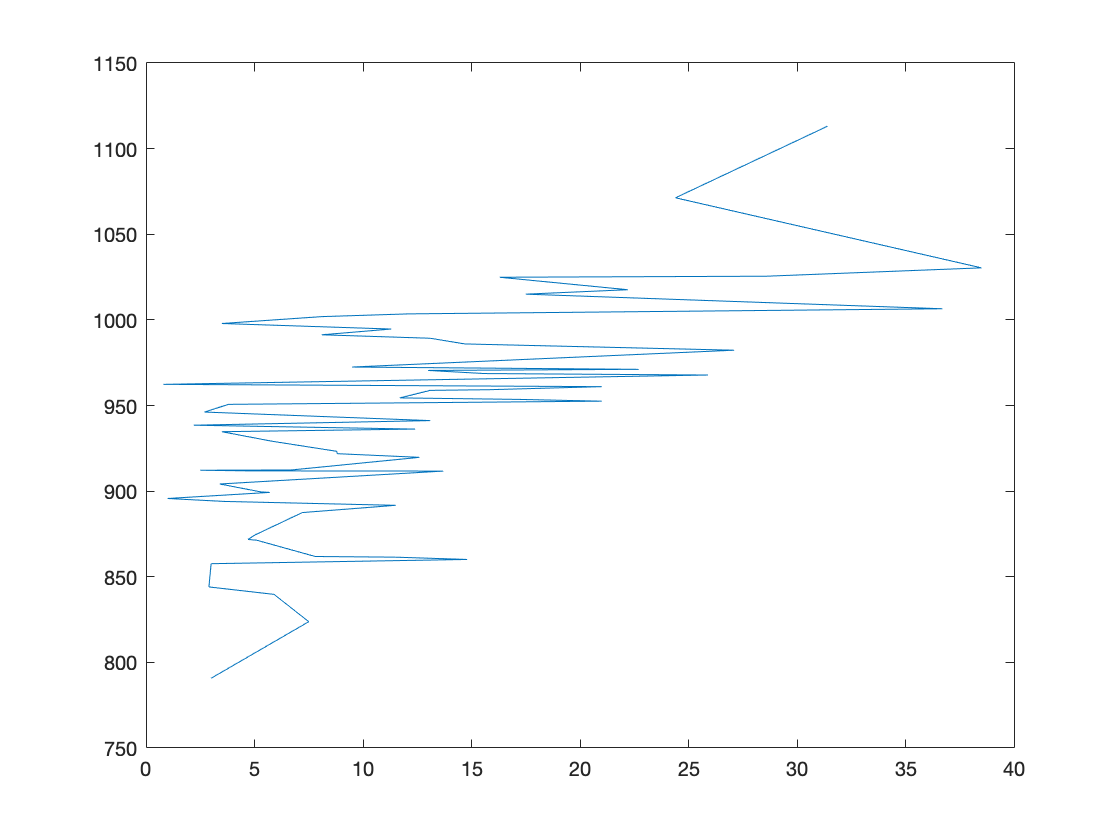

figure(7)
plot(X_ap(:,4), y)

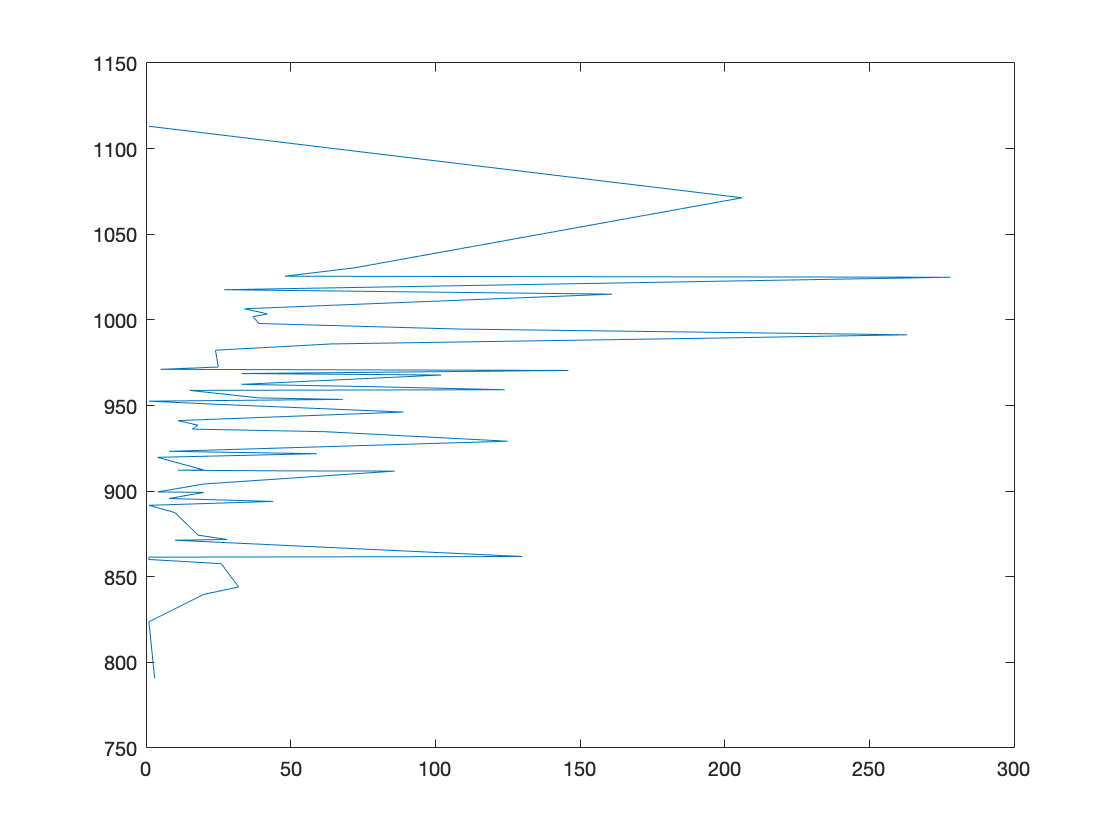

figure(8)
plot(X_ap(:,5), y)


X_ap_t = [ones(n,1) X_ap(:,[2 3]) log(X_ap(:,4)) log(X_ap(:,5))];
beta_hat_ap_t = inv(X_ap_t'*X_ap_t)*X_ap_t'*y

beta_hat_ap_t =   919.0881
    2.1568
  -15.9385
   31.3276
   14.9475


SS_R_ap_t = beta_hat_ap_t'*X_ap_t'*y - (sum(y))^2/n

SS_R_ap_t = 1.5313e+05

SS_res_ap_t = SS_tot - SS_R_ap_t

SS_res_ap_t = 7.5144e+04

MS_res_ap_t = SS_res_ap_t/(n-p)

MS_res_ap_t = 1.3663e+03

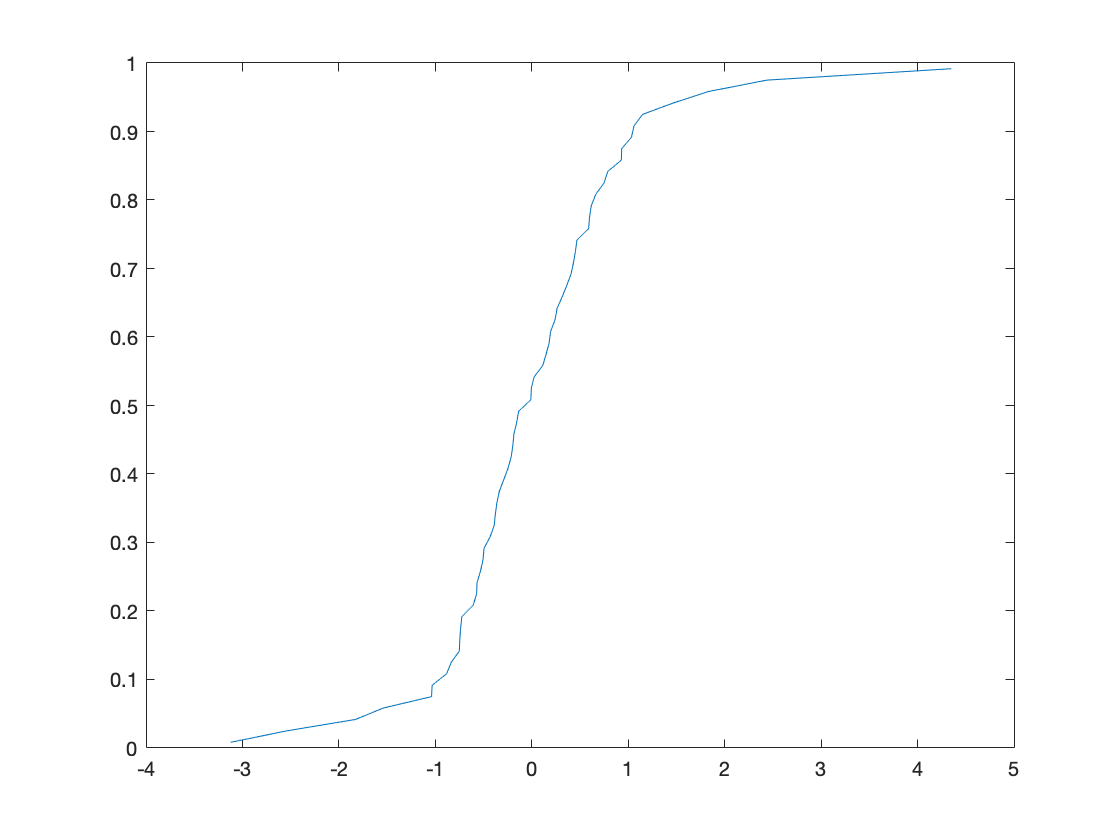


y_hat_ap_t = X_ap_t*beta_hat_ap_t;
e_ap_t = y - y_hat_ap_t;
H_ap_t = X_ap_t*inv(X_ap_t'*X_ap_t)*X_ap_t';

% Normality assumption

for i=1:n
    S_2i = ((n-p)*MS_res_ap_t - (e_ap_t(i))^2/(1-H_ap_t(i,i)))/(n-p-1);
    t_ap_t(i) = e_ap_t(i)/sqrt(S_2i*(1-H_ap_t(i,i)));
    r_ap_t(i) = e_ap_t(i)/sqrt(MS_res_ap_t*(1-H_ap_t(i,i)));
    P_ap_t(i) = (i-0.5)/n;
end
figure(9)
t_sorted = sort(t_ap_t)';
plot(t_sorted, P_ap_t);

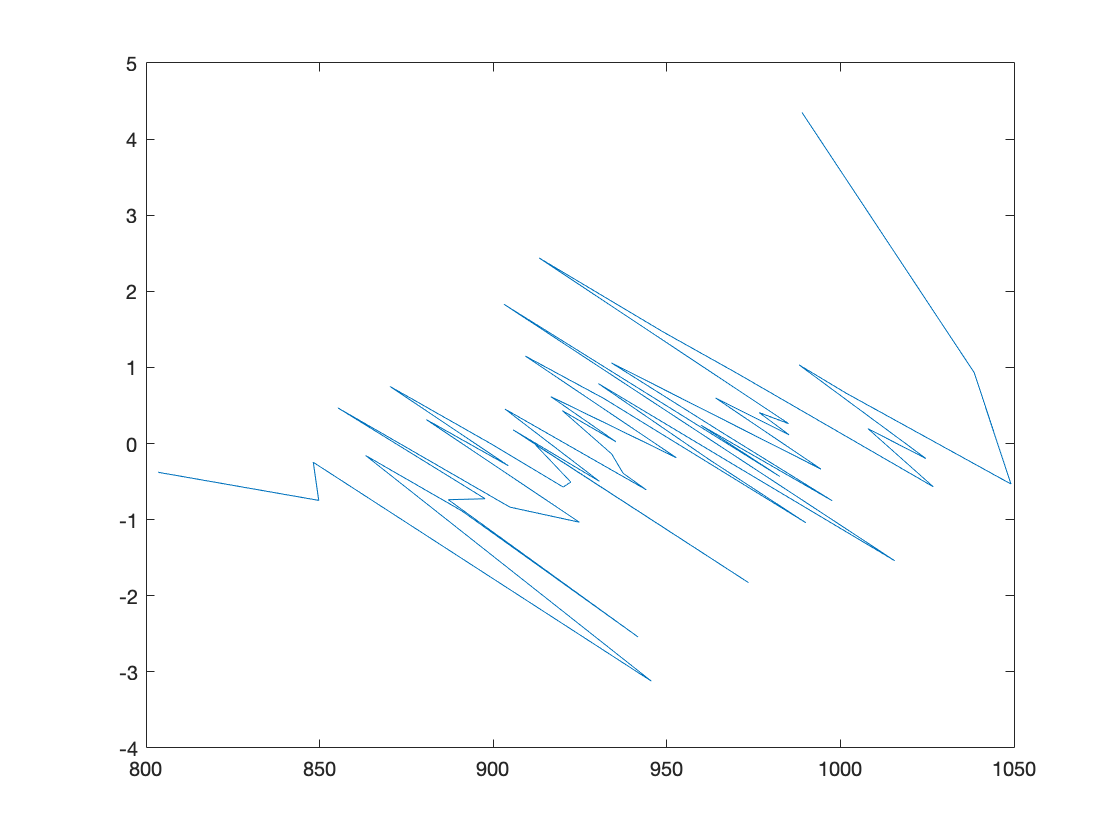


% Residual plots (SAVE PLOTS)
figure(10)
plot(y_hat_ap_t, t_ap_t);

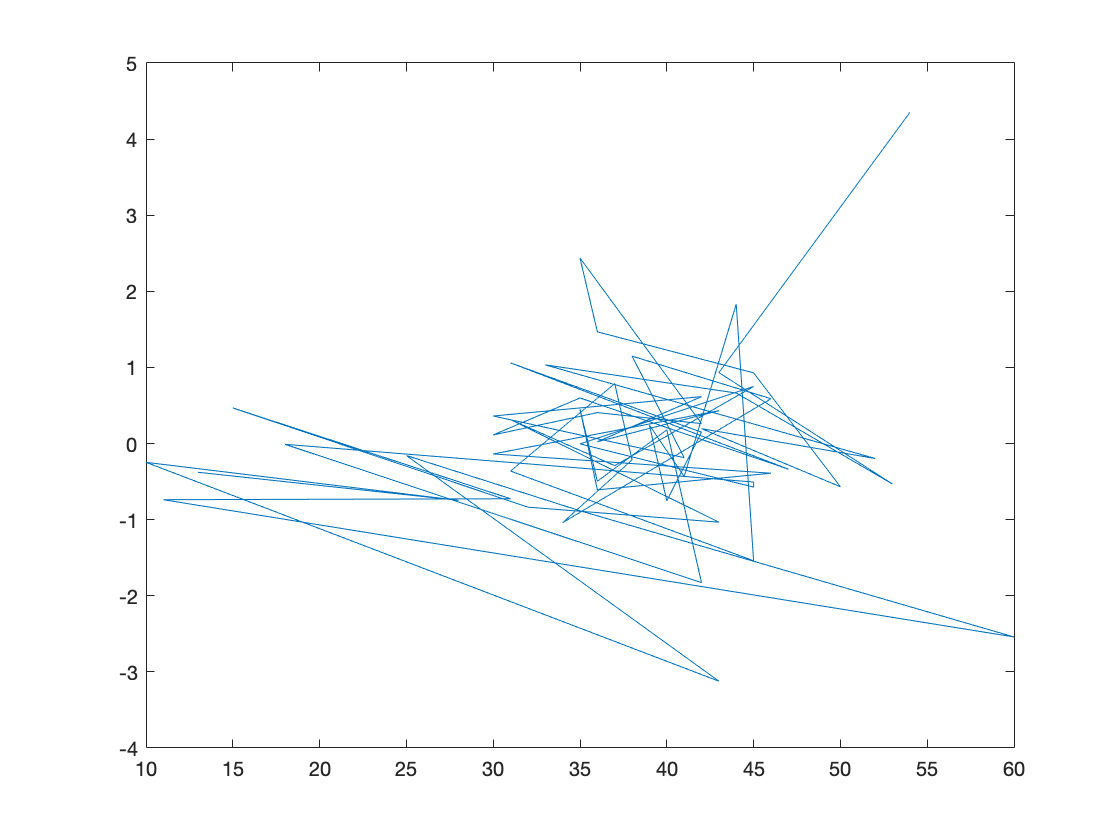

figure(11) 
plot(X_ap_t(:,2), t_ap_t); % x1

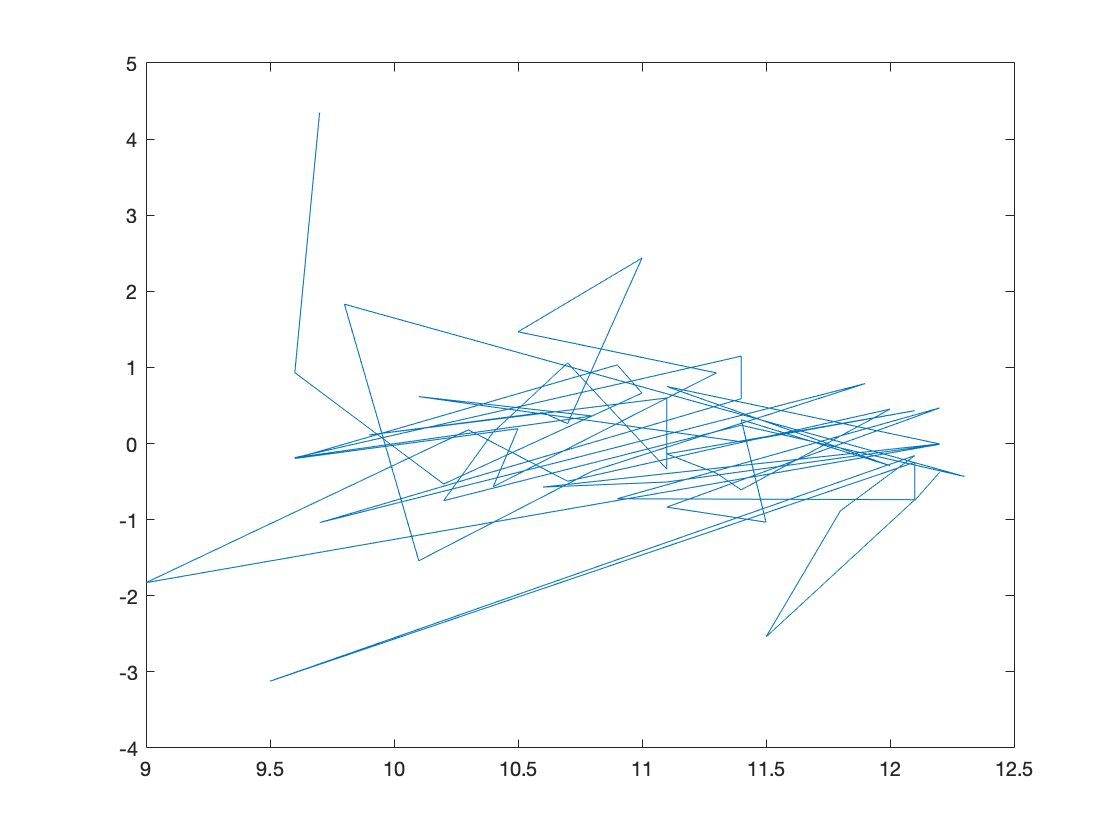

figure(12) 
plot(X_ap_t(:,3), t_ap_t); % x2

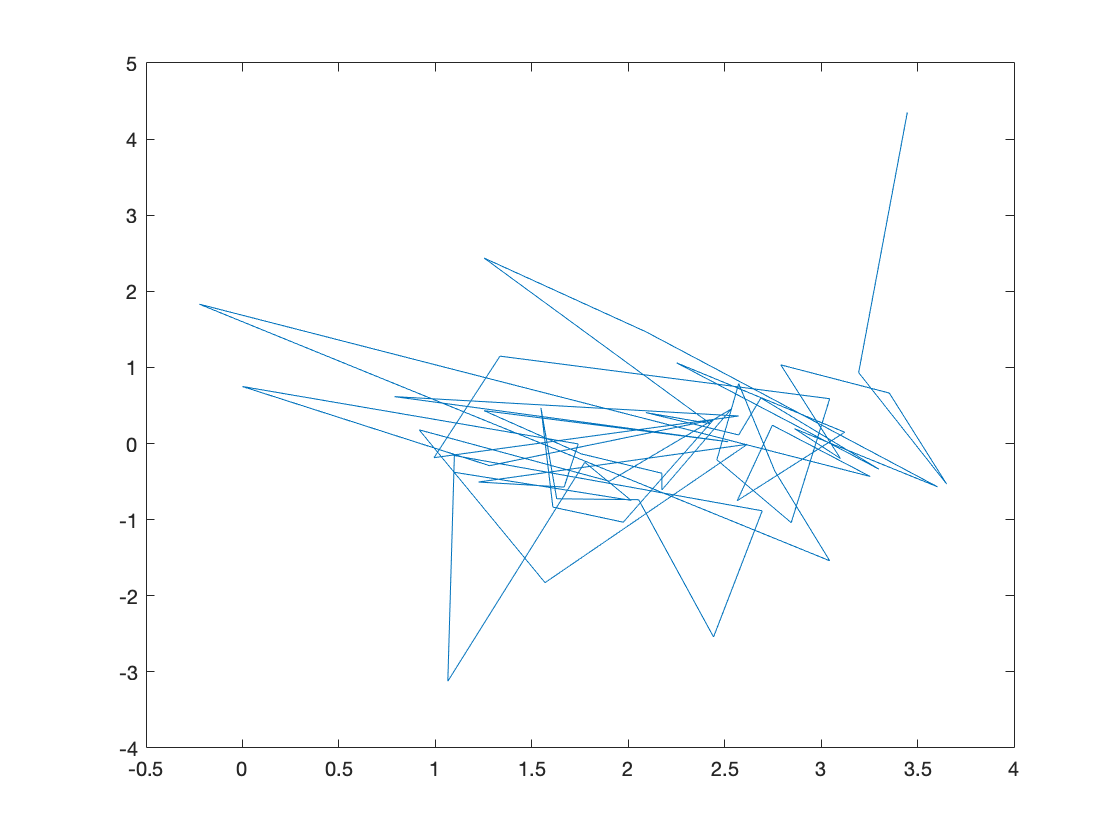

figure(13)
plot(X_ap_t(:,4), t_ap_t); % ln(x3)

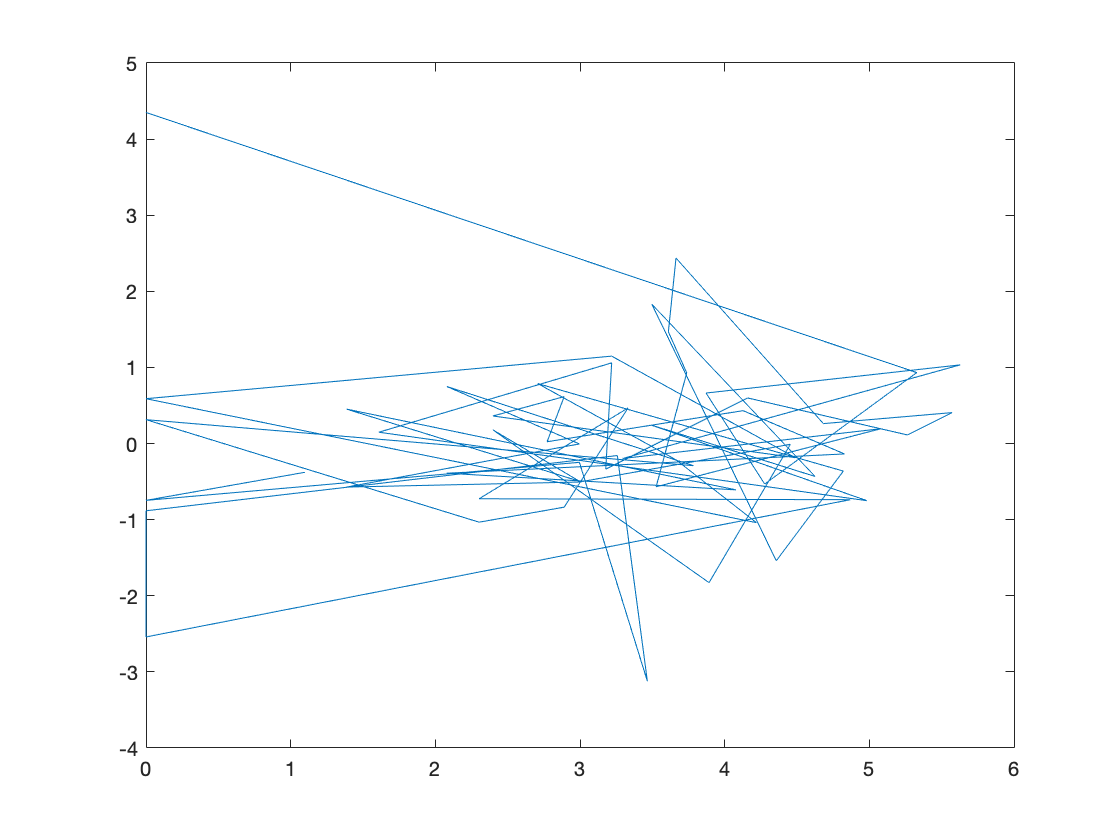

figure(14)
plot(X_ap_t(:,5), t_ap_t); % ln(x5)

Test for significance of regression:

alpha = 0.05;
MS_R_ap_t = SS_R_ap_t/(p-1);
MS_res_ap_t = SS_res_ap_t/(n-p);

F_0 = MS_R_ap_t/MS_res_ap_t

F_0 = 28.0203

F_crit = finv(1-alpha, p-1, n-p)

F_crit = 2.5397


% test for x1 coefficient

X_test_sig = [ones(n,1) X_ap_t(:,[3:5])];
beta_hat_sig = inv(X_test_sig'*X_test_sig)*X_test_sig'*y;
SS_R_sig = beta_hat_sig'*X_test_sig'*y - (sum(y))^2/n

SS_R_sig = 1.3535e+05

SS_R_diff = SS_R_ap_t - SS_R_sig

SS_R_diff = 1.7784e+04


F_0_sig = SS_R_diff/MS_res_ap_t

F_0_sig = 13.0169

F_crit_sig = finv(1-alpha, 1, n-p)

F_crit_sig = 4.0162


% test for x2 coefficient

X_test_sig = [ones(n,1) X_ap_t(:,[2 4:5])];
beta_hat_sig = inv(X_test_sig'*X_test_sig)*X_test_sig'*y;
SS_R_sig = beta_hat_sig'*X_test_sig'*y - (sum(y))^2/n

SS_R_sig = 1.4614e+05

SS_R_diff = SS_R_ap_t - SS_R_sig

SS_R_diff = 6.9943e+03


F_0_sig = SS_R_diff/MS_res_ap_t

F_0_sig = 5.1194

F_crit_sig = finv(1-alpha, 1, n-p)

F_crit_sig = 4.0162


% test for ln(x3) coefficient

X_test_sig = [ones(n,1) X_ap_t(:,[2:3 5])];
beta_hat_sig = inv(X_test_sig'*X_test_sig)*X_test_sig'*y;
SS_R_sig = beta_hat_sig'*X_test_sig'*y - (sum(y))^2/n

SS_R_sig = 1.1369e+05

SS_R_diff = SS_R_ap_t - SS_R_sig

SS_R_diff = 3.9443e+04


F_0_sig = SS_R_diff/MS_res_ap_t

F_0_sig = 28.8697

F_crit_sig = finv(1-alpha, 1, n-p)

F_crit_sig = 4.0162


% test for ln(x5) coefficient

X_test_sig = [ones(n,1) X_ap_t(:,[2:4])];
beta_hat_sig = inv(X_test_sig'*X_test_sig)*X_test_sig'*y;
SS_R_sig = beta_hat_sig'*X_test_sig'*y - (sum(y))^2/n

SS_R_sig = 1.2828e+05

SS_R_diff = SS_R_ap_t - SS_R_sig

SS_R_diff = 2.4851e+04


F_0_sig = SS_R_diff/MS_res_ap_t

F_0_sig = 18.1890

F_crit_sig = finv(1-alpha, 1, n-p)

F_crit_sig = 4.0162

Test for model validation with transformed model:

SS_PRESS = 0;
for i=1:n
    SS_PRESS = SS_PRESS + (e_ap_t(i)/(1-H_ap_t(i,i)))^2;
end

SS_PRESS % PRESS (prediction residual) sum of squares 

SS_PRESS = 9.8578e+04

R2_pred = 1- (SS_PRESS/SS_tot)

R2_pred = 0.5682

Now delete half of observations (randomly) and refit regression model (have outliers in the test set iobservations 4, 7, 50)

X_train = X_ap_t;
X_test = X_ap_t;
y_train = y;
y_test = y;

X_train([3:8 11 13 16 18 23:25 27:28 30 32 38 42:43 47:51 53 55:56 58 60], :) = []; % set up training/test sets
y_train([3:8 11 13 16 18 23:25 27:28 30 32 38 42:43 47:51 53 55:56 58 60]) = [];
X_test([1:2 9:10 12 14:15 17 19:22 26 29 31 33:37 39:41 44:46 52 54 57 59], :) = [];
y_test([1:2 9:10 12 14:15 17 19:22 26 29 31 33:37 39:41 44:46 52 54 57 59]) = [];

beta_hat_train = inv(X_train'*X_train)*X_train'*y_train

beta_hat_train =   788.7617
    3.0286
   -6.9976
   24.6542
   19.5730


y_pred = X_test*beta_hat_train;

e_pred = y_test - y_pred; % prediction errors

PRESS_test = sum(e_pred.^2)

PRESS_test = 6.1641e+04

SS_T_pred = y_test'*y_test - (sum(y_test))^2/30;
R2_pred_test = 1 - PRESS_test/SS_T_pred

R2_pred_test = 0.5205

Build another regression model using stepwise regression (x1, x2, ln(x3), x4, ln(x5)):

% X_step = ones(n,1);
% X_step_full = [X_ap_t(:,[1 2 3 4]) X(:,5) X_ap_t(:,5)]
% alpha_in = 0.1;
% alpha_out = 0.15;
% 
% % add first regressor 
% 
% F_in = finv(1-alpha_in, 1, n-2);
% 
% for i=1:K
%     X_test = [X_step X_step_full(:,i+1)];
%     beta_hat_test = inv(X_test'*X_test)*X_test'*y;
%     SS_R = beta_hat_test'*X_test'*y - (sum(y))^2/n;
%     SS_res = y'*y - beta_hat_test'*X_test'*y;
%     MS_res = SS_res/(n-2);
%     F_test = SS_R/MS_res;
%     
%     if F_test > F_in % add regressor if significant
%         X_add = X_test(:,2);
%         F_in = F_test; % determine if there is greater F-test score
%     end    
% end
% 
% X_step = [X_step X_add]; % added ln(X_3)
% beta_hat_old = inv(X_step'*X_step)*X_step'*y;
% SS_R_old = beta_hat_old'*X_step'*y - (sum(y))^2/n;
% X_add = [];
% 
% % add second regressor, check x1 against F_out
% 
% F_in = finv(1-alpha_in, 1, n-3);
% F_out = finv(1-alpha_out, 1, n-3);
% 
% for i=1:K
%     if i==3
%         continue
%     end
%     X_test = [X_step X_step_full(:,i+1)];
%     beta_hat_test = inv(X_test'*X_test)*X_test'*y;
%     SS_R = beta_hat_test'*X_test'*y - (sum(y))^2/n;
%     SS_R_diff = SS_R - SS_R_old;
%     SS_res = y'*y - beta_hat_test'*X_test'*y;
%     MS_res = SS_res/(n-3);
%     F_test = SS_R_diff/MS_res;
%     
%     if F_test > F_in % add regressor if significant
%         X_add = X_test(:,3);
%         F_in = F_test; % determine if there is greater F-test score
%     end    
% end % added x2
% 
% X_step = [X_step X_add];
% beta_hat_old = inv(X_step'*X_step)*X_step'*y;
% SS_R_old = beta_hat_old'*X_step'*y - (sum(y))^2/n;
% SS_res_old = SS_tot - SS_R_old;
% X_add = [];
% 
% x_remove = [];
% for i=1:size(X_step ,2)-2
%     X_test_out = X_step;
%     X_test_out(:,i+1) = [];
%     beta_hat_out = inv(X_test_out'*X_test_out)*X_test_out'*y;
%     SS_R_out = beta_hat_out'*X_test_out'*y - (sum(y))^2/n;
%     SS_R_out_diff = SS_R_old - SS_R_out;
%     SS_res_out = SS_res_old;
%     MS_res_out = SS_res_out/(n-3);
%     F_test_out = SS_R_out_diff/MS_res_out;
%     
%     if F_test_out < F_out
%         x_remove = [x_remove i];
%     end
% end
% 
% X_step(:,x_remove) = []; % none removed
% 
% % add third regressor, check x1, x2 against F_out
% 
% F_in = finv(1-alpha_in, 1, n-4);
% F_out = finv(1-alpha_out, 1, n-4);
% 
% for i=1:K
%     if i==2 || i==3
%         continue
%     end
%     X_test = [X_step X_step_full(:,i+1)];
%     beta_hat_test = inv(X_test'*X_test)*X_test'*y;
%     SS_R = beta_hat_test'*X_test'*y - (sum(y))^2/n;
%     SS_R_diff = SS_R - SS_R_old;
%     SS_res = y'*y - beta_hat_test'*X_test'*y;
%     MS_res = SS_res/(n-4);
%     F_test = SS_R_diff/MS_res;
%     
%     if F_test > F_in % add regressor if significant
%         X_add = X_test(:,4);
%         F_in = F_test; % determine if there is greater F-test score
%     end    
% end % added ln(x5)
% 
% X_step = [X_step X_add];
% beta_hat_old = inv(X_step'*X_step)*X_step'*y;
% SS_R_old = beta_hat_old'*X_step'*y - (sum(y))^2/n;
% SS_res_old = SS_tot - SS_R_old;
% X_add = [];
% 
% x_remove = [];
% for i=1:size(X_step ,2)-2
%     X_test_out = X_step;
%     X_test_out(:,i+1) = [];
%     beta_hat_out = inv(X_test_out'*X_test_out)*X_test_out'*y;
%     SS_R_out = beta_hat_out'*X_test_out'*y - (sum(y))^2/n;
%     SS_R_out_diff = SS_R_old - SS_R_out;
%     SS_res_out = SS_res_old;
%     MS_res_out = SS_res_out/(n-4);
%     F_test_out = SS_R_out_diff/MS_res_out;
%     
%     if F_test_out < F_out
%         x_remove = [x_remove i];
%     end
% end
% 
% X_step(:,x_remove) = [];
% 
% % add fourth regressor, check x1, x2 x8 against F_out
% 
% F_in = finv(1-alpha_in, 1, n-5);
% F_out = finv(1-alpha_out, 1, n-5);
% 
% for i=1:K
%     if i==2 || i==3 || i==5
%         continue
%     end
%     X_test = [X_step X_step_full(:,i+1)];
%     beta_hat_test = inv(X_test'*X_test)*X_test'*y;
%     SS_R = beta_hat_test'*X_test'*y - (sum(y))^2/n;
%     SS_R_diff = SS_R - SS_R_old;
%     SS_res = y'*y - beta_hat_test'*X_test'*y;
%     MS_res = SS_res/(n-5);
%     F_test = SS_R_diff/MS_res;
%     
%     if F_test > F_in % add regressor if significant
%         X_add = X_test(:,5);
%         F_in = F_test; % determine if there is greater F-test score
%     end    
% end % DID NOT ADD ANOTHER REGRESSOR - STOPPED
% 
% % Model adequacy checks
% 
% beta_hat_step = inv(X_step'*X_step)*X_step'*y
% y_hat_step = X_step*beta_hat_step;
% SS_R_step = beta_hat_step'*X_step'*y - (sum(y))^2/n
% SS_res_step = SS_tot - SS_R_step
% MS_res_step = SS_res_step/(n-4) % 4 coefficients
% e_step = y - y_hat_step;
% H_step = X_step*inv(X_step'*X_step)*X_step';
% 
% for i=1:n
%     S_2i = ((n-4)*MS_res_step - (e_step(i))^2/(1-H_step(i,i)))/(n-5);
%     t_step(i) = e_step(i)/sqrt(S_2i*(1-H_step(i,i)));
%     r_step(i) = e_step(i)/sqrt(MS_res_step*(1-H_step(i,i)));
%     P_step(i) = (i-0.5)/n;
% end
% figure(15)
% t_sorted = sort(t_step)';
% plot(t_sorted, P_ap_t);
% 
% % Residual plots (SAVE PLOTS)
% figure(16)
% plot(y_hat_step, t_step);
% figure(17) 
% plot(X_step(:,2), t_step); % x2
% figure(18) 
% plot(X_step(:,3), t_step); % ln(x3)
% figure(19)
% plot(X_step(:,4), t_step); % ln(x5)

Test for model validation with transformed model:

% SS_PRESS_step = 0;
% for i=1:n
%     SS_PRESS_step = SS_PRESS_step + (e_step(i)/(1-H_step(i,i)))^2;
% end
% 
% SS_PRESS_step % PRESS (prediction residual) sum of squares 
% R2_pred_step = 1- (SS_PRESS_step/SS_tot)

Use same test/training sets and refit regression model (have outliers in the test set iobservations 4, 7, 50)

% X_train = X_step;
% X_test = X_step;
% y_train = y;
% y_test = y;
% 
% X_train([3:8 11 13 16 18 23:25 27:28 30 32 38 42:43 47:51 53 55:56 58 60], :) = []; % set up training/test sets
% y_train([3:8 11 13 16 18 23:25 27:28 30 32 38 42:43 47:51 53 55:56 58 60]) = [];
% X_test([1:2 9:10 12 14:15 17 19:22 26 29 31 33:37 39:41 44:46 52 54 57 59], :) = [];
% y_test([1:2 9:10 12 14:15 17 19:22 26 29 31 33:37 39:41 44:46 52 54 57 59]) = [];
% 
% beta_hat_train = inv(X_train'*X_train)*X_train'*y_train
% y_pred = X_test*beta_hat_train;
% 
% e_pred = y_test - y_pred; % prediction errors
% 
% PRESS_test_step = sum(e_pred.^2)
% SS_T_pred = y_test'*y_test - (sum(y_test))^2/30;
% R2_pred_test_step = 1 - PRESS_test_step/SS_T_pred